clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref



s = tf('s');
unc = [param.model.B(1,:)-param.model.B_Bar(1,:);
        param.model.B(4,:)-param.model.B_Bar(4,:)
        param.model.B(7,:)-param.model.B_Bar(7,:)
        param.model.B(10,:)-param.model.B_Bar(10,:)];
Wdelta = unc*tf([1],[1]);
WdeltaTF2SS = ss(Wdelta);
param.model.Dwd = WdeltaTF2SS.D;


## Same real uncertainty for every input


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param.ctrl.Ks = control.DesignProcedureWeightedRealUncertainties(param,0,{[-1,1]});

ans =     0.1717   -0.0131   -0.0076   -0.0092
   -0.0359    0.1954   -0.0176   -0.0212
   -0.0337   -0.0282    0.2016   -0.0404
   -0.0310   -0.0260   -0.0309    0.1751


Evaluation of design procedure for weighted real uncertainties 
Q is positive definite


ans =     0.1702    0.1714    0.1717    0.1744    0.5674    0.5684    0.5686    0.5743    2.0977    2.0991    2.0994    2.1022


Eigenvalues of the decoupled systems are all negative 


ans =   -3.2368 + 0.0000i  -0.5323 + 0.3915i  -0.5323 - 0.3915i  -3.3001 + 0.0000i  -0.5217 + 0.3948i  -0.5217 - 0.3948i  -3.2879 + 0.0000i  -0.5181 + 0.3967i  -0.5181 - 0.3967i  -3.1775 + 0.0000i  -0.5514 + 0.3885i  -0.5514 - 0.3885i


Eigenvalues of the coupled systems are all negative 


ans =   -1.9831 + 0.7765i  -1.9831 - 0.7765i  -2.0910 + 1.6687i  -2.0910 - 1.6687i  -2.0767 + 1.4807i  -2.0767 - 1.4807i  -2.1088 + 1.5722i  -2.1088 - 1.5722i  -0.5470 + 0.0000i  -0.4865 + 0.0000i  -0.4805 + 0.0000i  -0.4752 + 0.0000i


0.000000, -22.659969, -22.659969, -22.659969, 
0.000000, -0.000000, -1.045935, -1.045935, 


0.000000, 0.000000, -0.000000, -1.450038, 


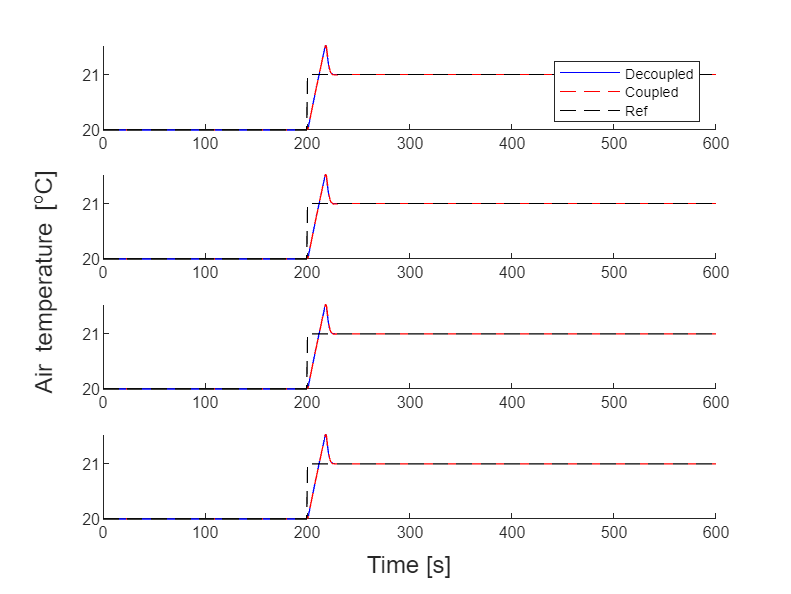

util.SimulateStep(param, "Examination_Weighted_Real_Uncertainties_Identical",0);

## Individual real uncertainty for every input


$$\Delta= 
\left[\matrix{\delta_1 & 0 & 0 & 0 \cr 0 & \delta_2 & 0 & 0 \cr
0 & 0 & \delta_3 & 0 \cr 0 & 0 & 0 & \delta_4}\right], \qquad \delta_i \in [-1,1], \quad i=1,2,3,4$$


param.ctrl.Ks = control.DesignProcedureWeightedRealUncertainties(param,0,{[-1,1],[-1,1],[-1,1],[-1,1]});

ans =     0.1717   -0.0131   -0.0076   -0.0092
   -0.0359    0.1954   -0.0176   -0.0212
   -0.0337   -0.0282    0.2016   -0.0404
   -0.0310   -0.0260   -0.0309    0.1751


Evaluation of design procedure for weighted real uncertainties 
Q is positive definite


ans =     0.1223    0.1281    0.1291    0.1309    0.5715    0.6038    0.6068    0.6137    2.5923    2.5952    2.5961    2.6018


Eigenvalues of the decoupled systems are all negative 


ans =   -3.9536 + 0.0000i  -0.3227 + 0.3969i  -0.3227 - 0.3969i  -3.8824 + 0.0000i  -0.3115 + 0.4068i  -0.3115 - 0.4068i  -3.8257 + 0.0000i  -0.3114 + 0.4083i  -0.3114 - 0.4083i  -3.8405 + 0.0000i  -0.3260 + 0.4100i  -0.3260 - 0.4100i


Eigenvalues of the coupled systems are all negative 


ans =   -3.8716 + 0.0000i  -3.6489 + 0.0000i  -3.4380 + 0.0000i  -3.5341 + 0.0000i  -0.5629 + 0.4085i  -0.5629 - 0.4085i  -0.7248 + 0.2997i  -0.7248 - 0.2997i  -0.7691 + 0.2825i  -0.7691 - 0.2825i  -0.8149 + 0.2324i  -0.8149 - 0.2324i


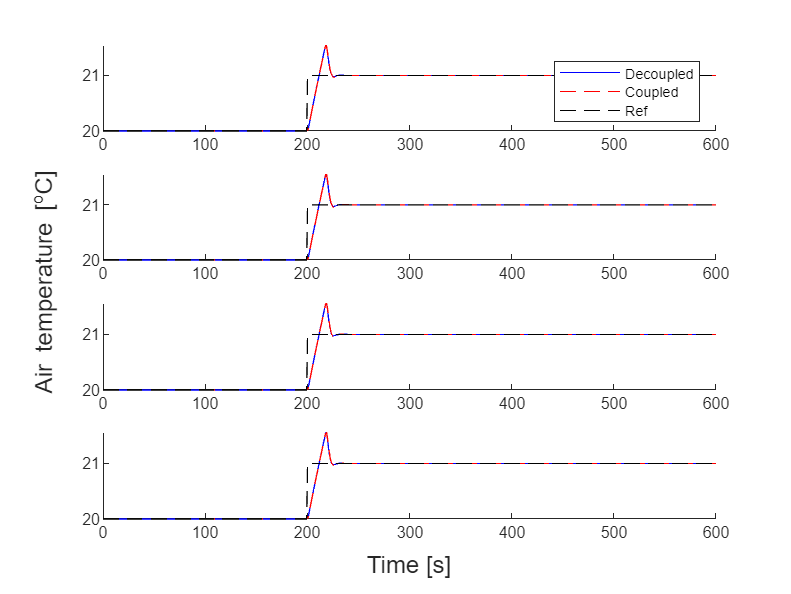

util.SimulateStep(param, "Examination_Weighted_Real_Uncertainties_Individual",0);